%Original paper: https://www.jneurosci.org/content/31/26/9481/tab-figures-data
%Figure 2D shows a normal/Gaussian distribution of spine sizes that I
%will do my darndest to simulate below (yes unfortunately this is the best
%I can do right now).


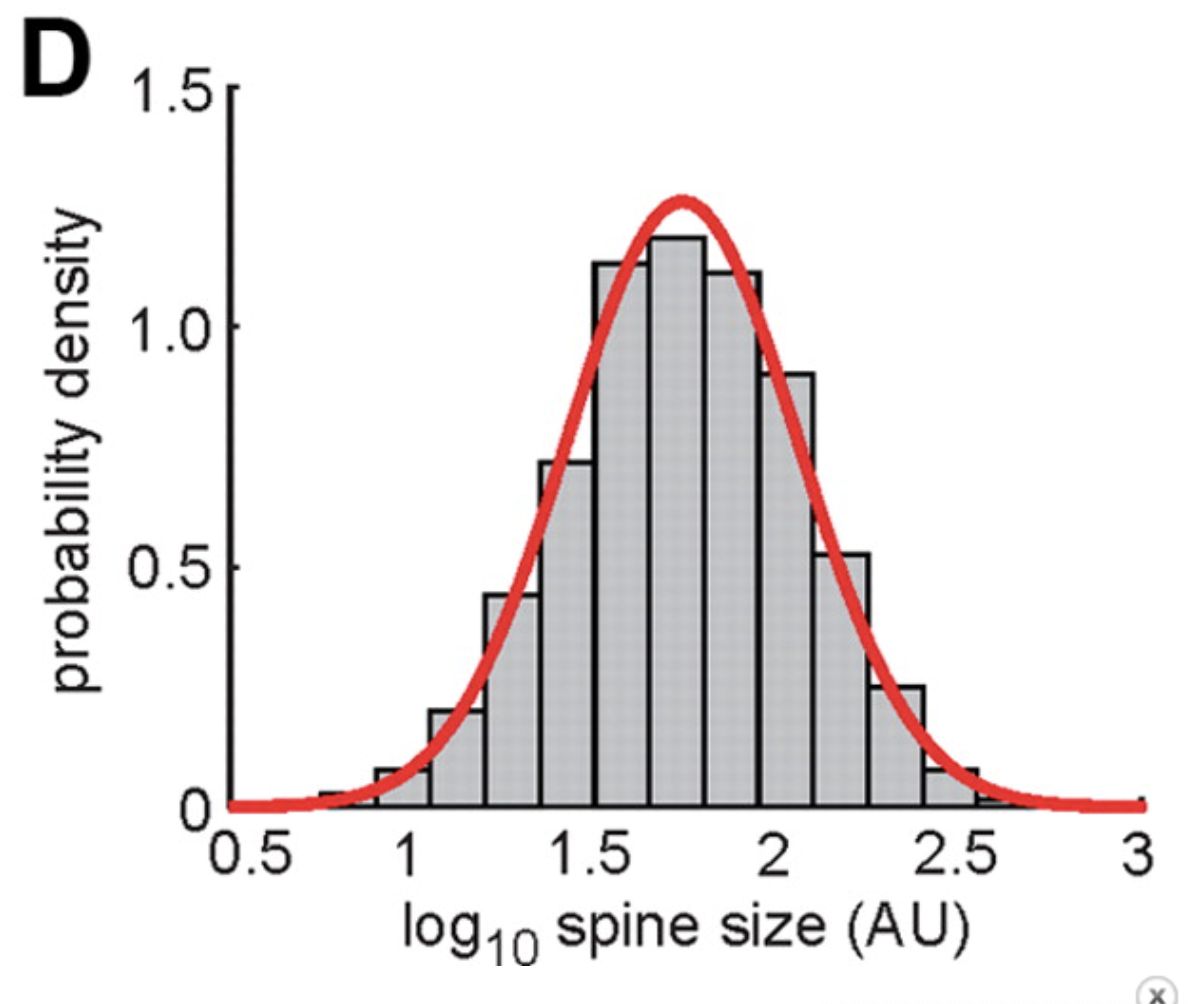

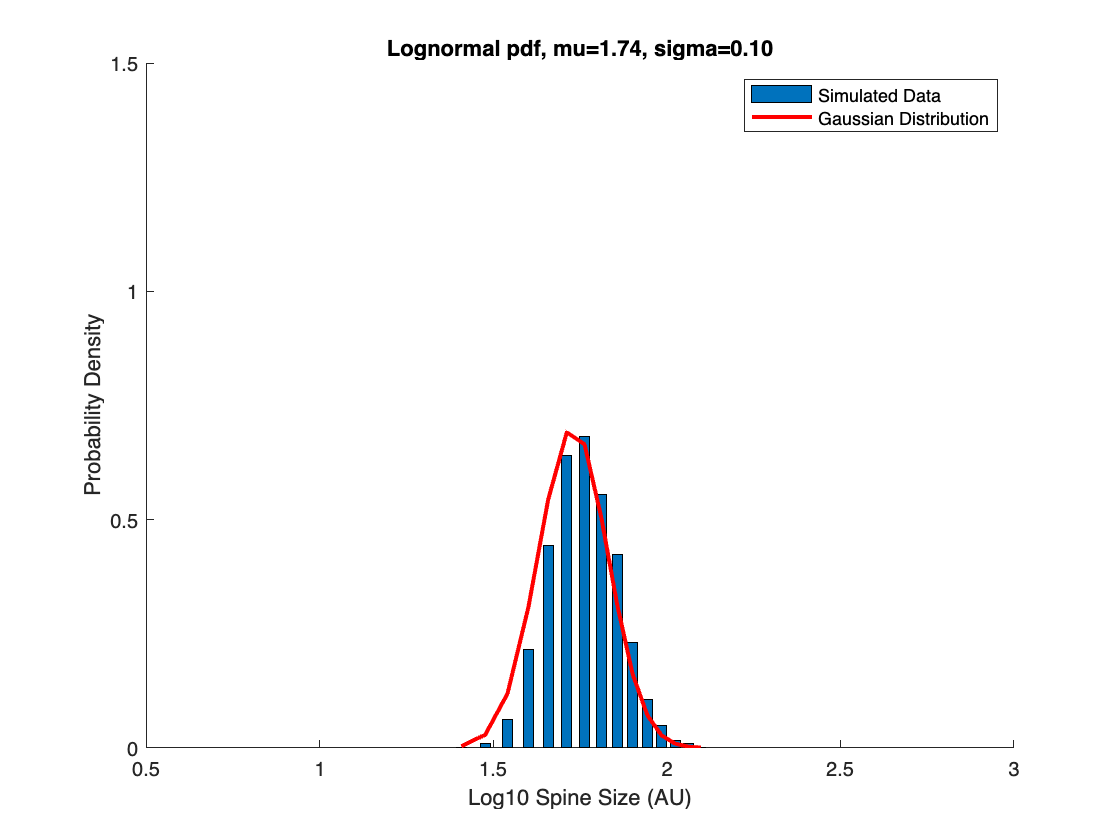

mu = 1.74;
sigma = 0.1002;
N = 3474;

% Get samples
samples = lognrnd(mu, sigma, N, 1);

% plot histogram, pick number of bins
cla reset; hold on;
nbins = 15;
[counts, edges] = histcounts(samples, nbins);
xaxis = edges(1:end-1)+diff(edges);
npdf = counts./trapz(xaxis, counts);
bar(log(xaxis), npdf);

% Show theoretical pdf in red
plot(log(xaxis), lognpdf(xaxis, mu, sigma), 'r-', 'LineWidth', 2);

% labels, ets
title(sprintf('Lognormal pdf, mu=%.2f, sigma=%.2f', mu, sigma))
xlabel('Log10 Spine Size (AU)');
axis([0.5 3 0 1.5]);

ylabel('Probability Density');
legend('Simulated Data', 'Gaussian Distribution')